# Image Formation of a USAF structure by the Optical Transfer Function

## Theoretical Background

Given the optical tranfer function (OTF) of an optical systems (yielded either by measurment, by simulation of the optical system or by specification) the image of an given object with radiance $L(x,y)$can be calculated. For simplicity, $m=1$ is assumed, magnification would just result in a scaling of the output:

Image and its spectrum before sampling including transfer function of sensor:


$$\tilde{E'}(u',v') =\text{FT}\{L(x',y')\}\cdot OTF(u',v') \cdot TF_{sensor} (u',v')$$



$$E'(x',y') = \text{FT}^{-1}\{\tilde{E'}(u',v')\}$$


Sampled image:


$$\Phi'(x',y') =E'(x',y') \cdot \frac{1}{h_{pp}^2}\cdot \text{comb}\left(\frac{x'}{h_{pp}},\frac{y'}{h_{pp}}\right)$$


Spectrum of sampled image:


$$\tilde{\Phi'}(u',v') = \tilde{E'}(u',v') \ast h_{pp}^2\cdot \text{comb}(h_{pp}\cdot u',h_{pp}\cdot v')$$


In this example here, the OTF of the Linos f=44 lens will be used.

## Parameter of simulation

N=4*512; % Sampling number

## Parameter of image sensor

h_pp=0.00465; % pixel pitch
c_ff=1; % fill factor
h_pix=h_pp*sqrt(c_ff); % pixel size

## Parameter of USAF structure pattern:

N_USAF=3;
u_q_USAF=(1:N_USAF)'/N_USAF * 2/3 *1/h_pp; % spatial frequencies in image plane
N_p=2.5; % number of periods of the structure

## Optical data of the lens

addpath(genpath('C:\Users\locsupp\Downloads\RTTB_v10\documented')) % Add folder and all subfolders of RTTB to search path

linos_f44=load_linos_f44();
[efl_linos_f44, bfl_linos_f44, ffl_linos_f44]=par_data_basic(linos_f44.n_surf, linos_f44.c, linos_f44.d, linos_f44.n);

#### OTF of lens from spot diagram with minimum rms

% w=0; % field angle
w=20/180*pi; 
N_trace_sq=51; % square root of number of rays
warning off, [r_pos,r_dir,OPL]=spot_diag_inf(linos_f44, w, N_trace_sq); warning on 
[r_dz_pos, OPL_dz, d_z]=spot_diag_min_rms(r_pos,r_dir,OPL,linos_f44.n(linos_f44.n_surf,1));
% set image plane to the desired value:
linos_f44.d(end)=bfl_linos_f44+d_z;
z_Pq=image_distance(linos_f44.d_P-linos_f44.d(1),linos_f44.n_surf, linos_f44.c, linos_f44.d, linos_f44.n)+sum(linos_f44.d(1:linos_f44.n_surf-1));
d_PqOq=sum(linos_f44.d(1:linos_f44.n_surf))-z_Pq;
% OTF:
[OTF, du_q, l_Pq]=rayspot2OTF(linos_f44,r_dz_pos,r_dir, OPL_dz, d_PqOq, N, h_pp);

#### Samplings from OTF

% sampling in spatial frequency domain
u_q=((0:N-1)-N/2)*du_q; v_q=u_q;
% sampling in image plane
dx_q=1/du_q/N; dy_q=dx_q;
x_q=((0:N-1)-N/2)*dx_q; y_q=x_q;
% sampling period in exit pupil
dy_Pq=d_PqOq*linos_f44.la(1)/(dy_q*N);

## Generation of USAF structure

[L,ind_USAF_center,ind_size_pat]=USAF(u_q_USAF,N_p,x_q,N);

## Calculate Fourier transform of USAF structure

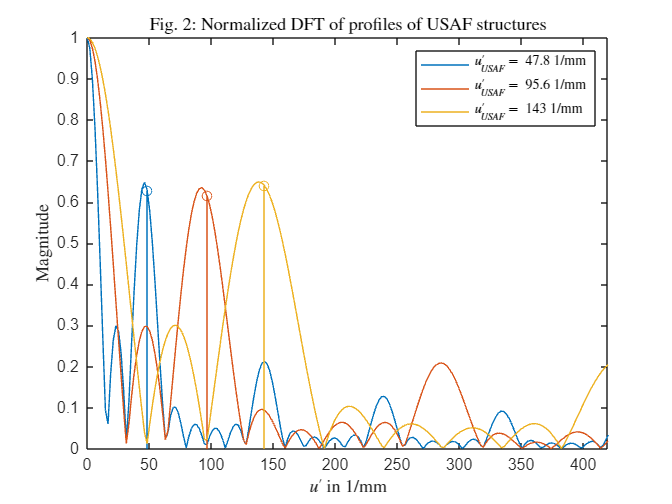

L_DFT = fftshift(fft2(ifftshift(L)));

L_profile=L(ind_USAF_center,:);
L_DFT_profile=fftshift(fft(ifftshift(L_profile',1)),1);

[min_u_q_USAF,ind_u_q_USAF]=min(abs(repmat(u_q,N_USAF,1)-u_q_USAF),[],2);

figure()
c_ord = colororder;
for i=1:N_USAF
    plot(u_q',abs(L_DFT_profile(:,i)/L_DFT_profile(N/2+1,i)),'Color',c_ord(i,:)), hold on
    stem(u_q(ind_u_q_USAF(i)),abs(L_DFT_profile(ind_u_q_USAF(i),i)/L_DFT_profile(N/2+1,i)),'Color',c_ord(i,:))
end
xlim([0 2*linos_f44.l_P/efl_linos_f44/linos_f44.la(1)])
xlabel(['$u''$ in 1/mm'],'Interpreter','Latex')
ylabel('Magnitude','Interpreter','Latex')
title('Fig. 2: Normalized DFT of profiles of USAF structures','Interpreter','latex')
lgd_str={['$u''_{USAF} =$ ' num2str(u_q_USAF(1),3) ' 1/mm'],''};
for i=2:N_USAF
    lgd_str={lgd_str{:}, ['$u''_{USAF} =$ ' num2str(u_q_USAF(i),3) ' 1/mm'],''};
end
legend(lgd_str,'Interpreter','Latex')

Notice: Compare amplitude of base freqeuency to $2/\pi\approx \text{0.64}$ from first order of Fourier series expansion of rect-function

## Transfer Function of sensor


$$TF_{sensor}(u',v') =h_{pix}^2 \cdot \text{sinc}(h_{pix}\cdot u') \cdot \text{sinc}(h_{pix}\cdot v')$$


TF_sensor=sinc(h_pix*u_q)'.*sinc(h_pix*v_q);

## Calculate the system response (i.e. the image before sampling)

Assuming a constant OTF over the field, the system resonse is the inverse Fourier transform of the product of the transfer function with the FT of the input:


$$E'(x,y) = \text{FT}^{-1}\{\text{FT}\{L(x',y')\}\cdot OTF(u',v') \cdot TF_{sensor}(u',v')\} $$


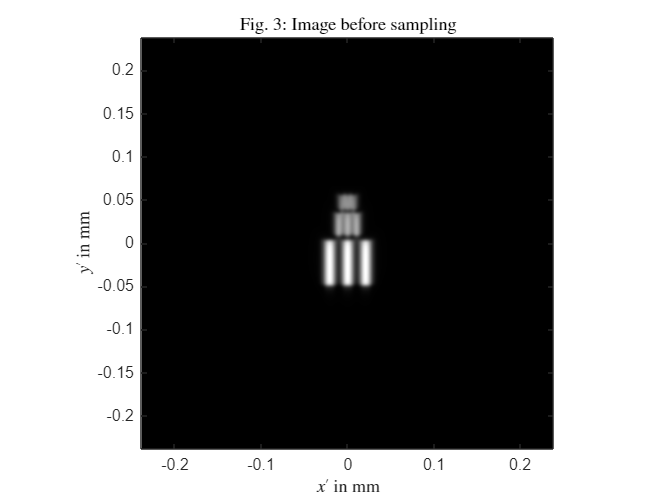

E_q = fftshift(ifft2(ifftshift(L_DFT.*OTF.*TF_sensor)));

figure()
imagesc(x_q,y_q,abs(E_q)); % amplitude distribution of exit pupil
set(gca,'YDir','normal')
colormap(gray) 
axis square 
title('Fig. 3: Image before sampling','Interpreter','Latex')
xlabel('$x''$ in mm','Interpreter','Latex')
ylabel('$y''$ in mm','Interpreter','Latex')

#### Profiles of image before sampling

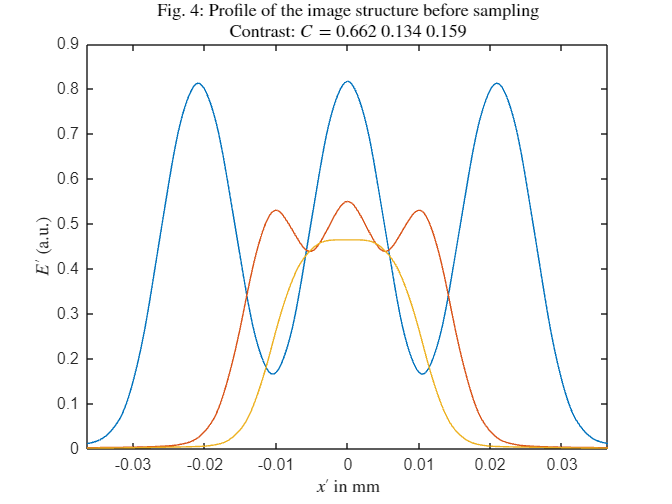

E_q_profile=E_q(ind_USAF_center,:);

% Contrast of profiles
E_q_max=NaN(N_USAF,1); E_q_min=NaN(N_USAF,1);
for i=1:N_USAF
    E_q_max(i)=max(E_q_profile(i,ind_size_pat(i,:)));
    E_q_min(i)=min(E_q_profile(i,ind_size_pat(i,:)));
end
C=(E_q_max-E_q_min)./(E_q_max+E_q_min);

figure()
plot(x_q, E_q_profile)
ind_xlim1=find(sum(ind_size_pat,1)>=1,1,'first');ind_xlimend=find(sum(ind_size_pat,1)>=1,1,'last');
xlim_x_q_USAF=[x_q(ind_xlim1) x_q(ind_xlimend)]+[-1 1]*0.2*(x_q(ind_xlimend) -x_q(ind_xlim1));
xlim(xlim_x_q_USAF)
xlabel('$x''$ in mm','Interpreter','Latex')
ylabel('$E''$ (a.u.)','Interpreter','Latex')
title({'Fig. 4: Profile of the image structure before sampling'; ...
    ['Contrast: $C=$' num2str(C',3)]}, ...
    'Interpreter','Latex')

## Compare Transfer Functions and Contrast

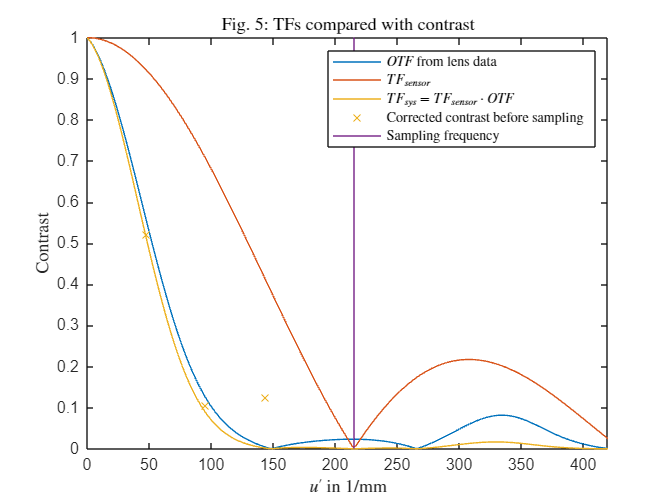

TF_sys=OTF.*TF_sensor;
% calculate profiles
dir='x'; % direction in the image plane ('x' or 'y')
if dir == 'x', dir_uv='u'; elseif dir=='y', dir_uv='v'; end

figure()
if dir == 'x'
    plot(u_q,abs(OTF(N/2+1,:)), u_q, abs(TF_sensor(N/2+1,:)),u_q,abs(TF_sys(N/2+1,:)))
elseif dir == 'y'
    plot(u_q,abs(OTF(:,N/2+1)), u_q, abs(TF_sensor(:,N/2+1)),u_q,abs(TF_sys(:,N/2+1)))
end
hold on
plot(u_q_USAF, C/4*pi, 'Marker','x', 'Color',c_ord(N_USAF,:),'LineStyle','none')
plot([1 1]/h_pp,[0 1], 'Color',c_ord(N_USAF+1,:))
xlim([0 2*linos_f44.l_P/efl_linos_f44/linos_f44.la(1)])
xlabel(['$' dir_uv '''$ in 1/mm'],'Interpreter','Latex')
ylabel('Contrast','Interpreter','Latex')
title('Fig. 5: TFs compared with contrast','Interpreter','latex')
legend({'$OTF$ from lens data',...
    '$TF_{sensor}$',...
    '$TF_{sys}=TF_{sensor} \cdot OTF$',...
    'Corrected contrast before sampling',...
    'Sampling frequency',...
    },'Interpreter','Latex')

#### Spectra of profiles of USAF image before sampling

% Extract data from the system transfer function (TF_sys)
if dir == 'x'
    tf_sys_data = abs(TF_sys(N/2+1,:));
else
    tf_sys_data = abs(TF_sys(:,N/2+1));
end

% Define the target contrast level
contrast_target = 0.5;

% Interpolate the data to find the frequency at 50% contrast
u_q_interp = linspace(min(u_q), max(u_q), 1000);  % Increase resolution
tf_sys_interp = interp1(u_q, tf_sys_data, u_q_interp, 'linear');

% Find the frequency where contrast is 50%
[~, contrast_idx] = min(abs(tf_sys_interp - contrast_target));
frequency_50_percent_contrast = u_q_interp(contrast_idx);

% Display the frequency at 50% contrast
disp(['The frequency at 50% contrast is: ' num2str(frequency_50_percent_contrast) ' 1/mm'])

The frequency at 50% contrast is: 48.4376 1/mm


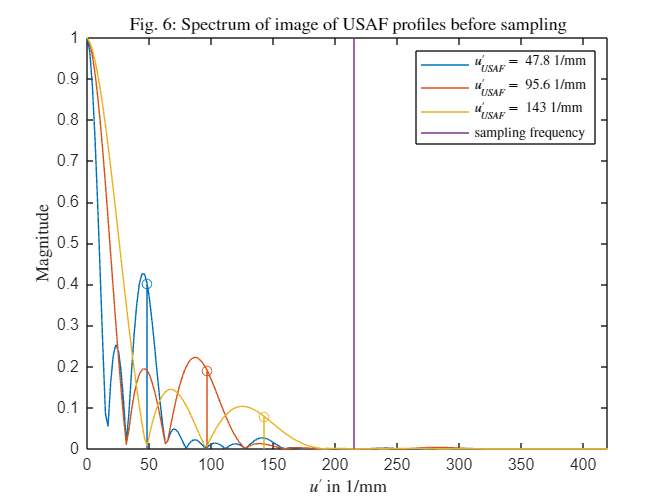





contrast_sys = abs(TF_sys(N/2+1,:));
contrast_lens = abs(OTF(N/2+1,:));
%u_q  

E_q_USAF_DFT_profile=L_DFT_profile.*repmat(TF_sys(:,N/2+1),1,N_USAF);

figure()
for i=1:N_USAF
    plot(u_q',abs(E_q_USAF_DFT_profile(:,i))./abs(L_DFT_profile(N/2+1,i)),'Color',c_ord(i,:)), hold on
    stem(u_q(ind_u_q_USAF(i)),abs(E_q_USAF_DFT_profile(ind_u_q_USAF(i),i))./abs(L_DFT_profile(N/2+1,i)),'Color',c_ord(i,:))
end
plot([1 1]/h_pp,[0 1], 'Color',c_ord(N_USAF+1,:))
xlim([0 2*linos_f44.l_P/efl_linos_f44/linos_f44.la(1)])
xlabel(['$u''$ in 1/mm'],'Interpreter','Latex')
ylabel('Magnitude','Interpreter','Latex')
title('Fig. 6: Spectrum of image of USAF profiles before sampling','Interpreter','latex')
legend({lgd_str{:},'sampling frequency'},'Interpreter','Latex')

## Sampling by the sensor

ind_pp=round(h_pp/dy_q); % sampling period (pixel pitch) in sampling units 
ind_sample_shift=round(0.4*ind_pp); % shift of sampling relative to centered sampling (in sampling units)
ind_1=1+mod(N/2,ind_pp)+ind_sample_shift; % starting index of sampling

#### Sampling


$$\Phi'(x,y) = E'(x,y) \cdot \frac{1}{h_{pp}^2}\cdot \text{comb}\left(\frac{x}{h_{pp}},\frac{y}{h_{pp}}\right)$$


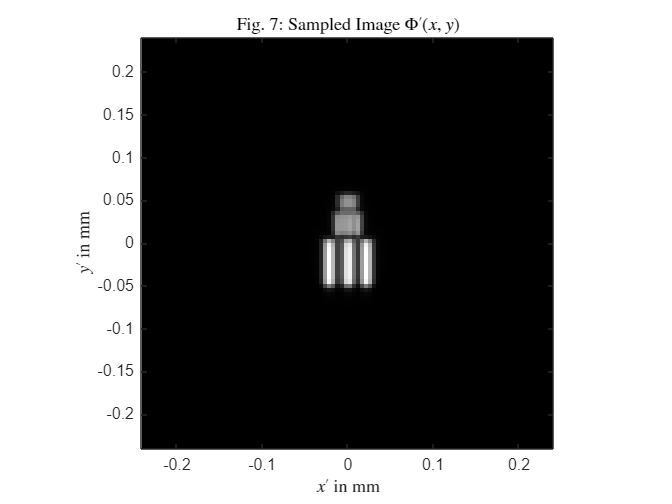

Phi_q_pix=E_q(ind_1:ind_pp:end,ind_1:ind_pp:end);

figure()
imagesc(x_q,y_q,abs(Phi_q_pix)); % amplitude distribution of exit pupil
set(gca,'YDir','normal')
colormap(gray) 
axis square 
title('Fig. 7: Sampled Image $\Phi''(x,y)$','Interpreter','Latex')
xlabel('$x''$ in mm','Interpreter','Latex')
ylabel('$y''$ in mm','Interpreter','Latex')

#### Profiles of sampled image

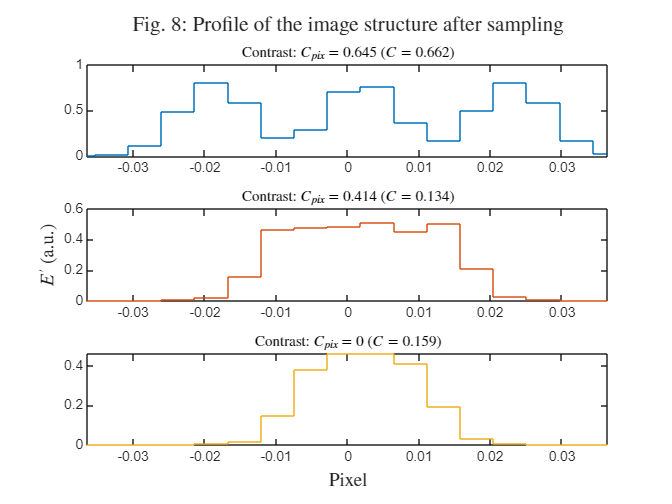

Phi_q_pix_profile=Phi_q_pix(round(ind_1/ind_pp)+round(ind_USAF_center/ind_pp),:);
x_q_pix=x_q(ind_1:ind_pp:end)';

% contrast of profiles
Phi_q_pix_max=NaN(N_USAF,1); Phi_q_pix_min=NaN(N_USAF,1);
for i=1:N_USAF
    Phi_q_pix_max(i)=max(Phi_q_pix_profile(i,ind_size_pat(i,1:ind_pp:end)));
    Phi_q_pix_min(i)=min(Phi_q_pix_profile(i,ind_size_pat(i,1:ind_pp:end)));
    if sum(diff(diff(Phi_q_pix_profile(i,ind_size_pat(i,1:ind_pp:end))))>0) < 2,
        Phi_q_pix_min(i)=Phi_q_pix_max(i); 
    end
end
C_pix=(Phi_q_pix_max-Phi_q_pix_min)./(Phi_q_pix_max+Phi_q_pix_min);

figure()
t=tiledlayout(N_USAF,1);
for i=1:N_USAF
    nexttile
    stairs(x_q_pix,Phi_q_pix_profile(i,:)','Color',c_ord(i,:))
    xlim(xlim_x_q_USAF)
    title(['Contrast: $C_{pix}=$' num2str(C_pix(i),3) ' ($C=$' num2str(C(i),3) ')'],'Interpreter','latex')
end
xlabel(t,'Pixel','Interpreter','Latex')
ylabel(t,'$E''$ (a.u.)','Interpreter','Latex')
title(t,{'Fig. 8: Profile of the image structure after sampling'}, ...
    'Interpreter','Latex')

#### Spectra of sampled image profils


$$\tilde{\Phi'}(u',v') = \tilde{E'}(u',v') \ast h_{pp}^2\cdot \text{comb}(h_{pp}\cdot u',h_{pp}\cdot v')$$


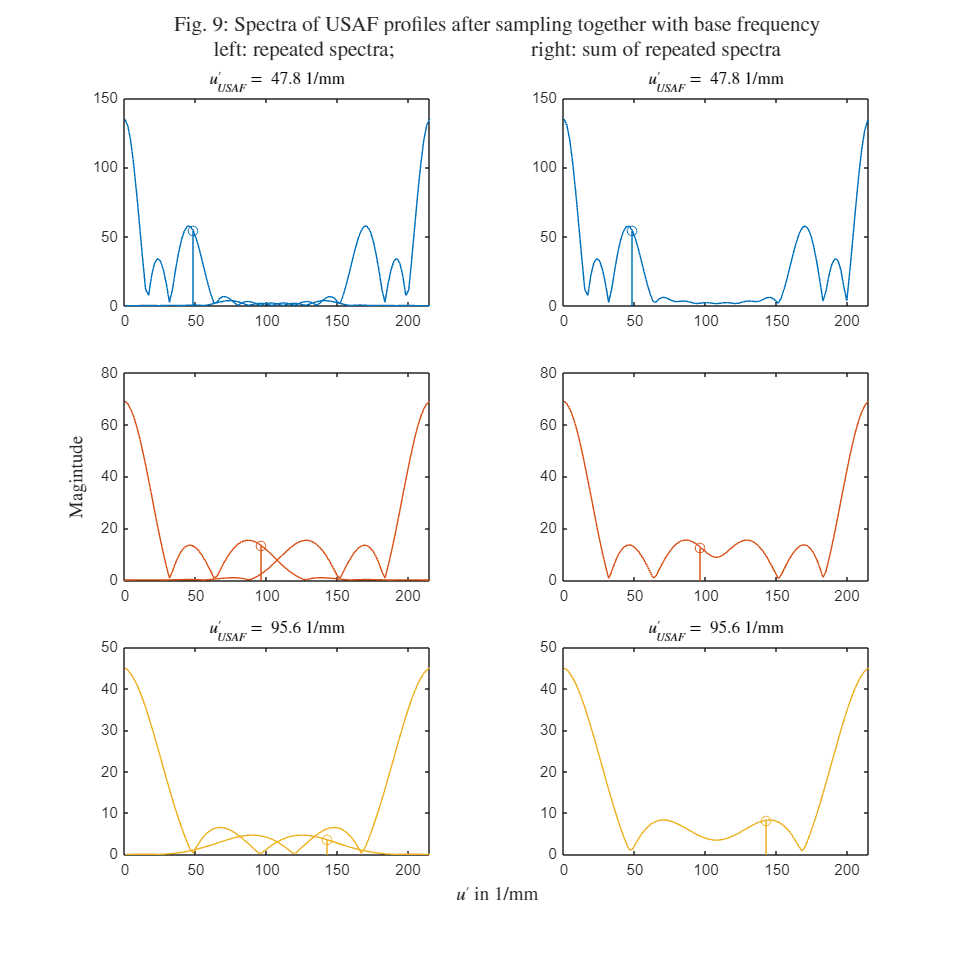

% Add up two repeated spectra including linear phase due to shift of sensor:
[min_USAF,ind_u_q_USAF]=min(abs(repmat(u_q,N_USAF,1)-u_q_USAF),[],2);
E_q_USAF_DFT_profile_sampled=E_q_USAF_DFT_profile+interp1(u_q'+1/h_pp,E_q_USAF_DFT_profile*exp(-j*2*pi*ind_sample_shift*dy_q/h_pp),u_q','spline');

figure('Position',[1 1 800 800])
t=tiledlayout(N_USAF,2);
C = colororder;
for i=1:N_USAF
    nexttile
    plot(u_q',abs(E_q_USAF_DFT_profile(:,i)),'Color',c_ord(i,:)), hold on
    plot(u_q+1/h_pp,abs(E_q_USAF_DFT_profile(:,i)),'Color',c_ord(i,:))
    stem(u_q(ind_u_q_USAF(i)),abs(E_q_USAF_DFT_profile(ind_u_q_USAF(i),i)),'Color',c_ord(i,:)), hold off
    xlim([0 1/h_pp])
    title(lgd_str{i},'Interpreter','latex')
    
    nexttile
    plot(u_q',abs(E_q_USAF_DFT_profile_sampled(:,i)),'Color',c_ord(i,:)), hold on
    stem(u_q(ind_u_q_USAF(i)),abs(E_q_USAF_DFT_profile_sampled(ind_u_q_USAF(i),i)),'Color',c_ord(i,:)), hold off
    xlim([0 1/h_pp])
    title(lgd_str{i},'Interpreter','latex')
end
xlabel(t,['$u''$ in 1/mm'],'Interpreter','Latex')
ylabel(t,'Magintude','Interpreter','Latex')
title(t,{'Fig. 9: Spectra of USAF profiles after sampling together with base frequency',...
    'left: repeated spectra; $\qquad \qquad \qquad$ right: sum of repeated spectra'},'Interpreter','latex')

## Experiments

Shift the lateral position of the sensor (L. 120: ind_sample_shift, e.g. ind_sample_shift=round(0.4*ind_pp) )

Change the number of periods of the USAF pattern to 4.5 (L. 4) 

## Observations

## Questions

## Local Functions

function linos_f44=load_linos_f44()
% Number of surfaces (including sensor surface)        
linos_f44.n_surf=8;
% Curvatures of lens surfaces:
linos_f44.c=[1/14.1;  0;  1/-29.6; 1/13.0; 1/-91.1;  1/14.57;  1/-21; 0];
% Distances from surface to surface:
linos_f44.d=[10;  2.76;  1.94;  1.49;  1.9;  1.07;  2.9;  38.19];
% Glasses (Schott): SK4;  F8;  KZFN2;  LAK31;
% linos_f44.la=[0.00058756 0.00048613 0.00065627]; % g b r  standard wavelength
% Refraction indices at specified wavelengths:
% linos_f44.n=[1.0  1.0  1.0;  1.6127203  1.6199982  1.6095434;  1.0  1.0  1.0;  ...
%    1.5955102  1.6062267  1.5910209;  1.0  1.0  1.0;  1.5294405  1.5365924   1.5263331;    ...
%    1.6967325  1.7053140  1.6929600; 1.0  1.0  1.0;]; 
linos_f44.la=0.00053; % wavelength of lab experiment
linos_f44.n=[1.0; 1.6163353; 1.0; 1.6007627; 1.0; 1.5329841; 1.7010020; 1.0];
% Typ of surface (a=0: spherical surface):
linos_f44.a=[0; 0; 0; 0; 0; 0; 0; 0;];
% Heights of surfaces
linos_f44.h=[5.5;  5.5;  5.0; 5.0;  5.5;  5.5;  5.5;  16.77];
% Max. field angle
linos_f44.w=22*pi/180;


% Position of the stop
d_stop=sum(linos_f44.d(1:4))+0.64; % data sheet: sum(linos_f44.d(1:4))
h_stop=4.07; % data sheet: 4.04

% Calculate entrance pupil from stop
[linos_f44.d_P, linos_f44.l_P]=find_EP(linos_f44.n_surf, linos_f44.d, linos_f44.c, linos_f44.n, d_stop, h_stop);
end

function [r_dz_pos, OPL_dz, d_z]=spot_diag_min_rms(r_pos,r_dir,OPL,n_q)
    pos_rms=plane_min_rms(r_pos, r_dir); 
    d_z=pos_rms(3); % defocus
    r_dz_pos=r_pos+r_dir(1:2,:)./repmat(r_dir(3,:),2,1)*d_z; % spots at defocus
    OPL_dz=OPL+n_q*d_z./r_dir(3,:); 
end

function  [OTF, du_q, l_Pq]=rayspot2OTF(opt_sys,r_pos,r_dir, OPL, d_PqOq,N, h_pp, y_max)
    r_Pq_pos=r_pos+r_dir(1:2,:)./repmat(r_dir(3,:),2,1)*(-d_PqOq);
    OPL_Pq=OPL+opt_sys.n(opt_sys.n_surf,1)*(-d_PqOq)./r_dir(3,:); 
    % subtract spherical wave
    OPD_Pq=OPL_Pq+opt_sys.n(opt_sys.n_surf,1)*sqrt(r_Pq_pos(1,:).^2+(r_Pq_pos(2,:)-mean(r_pos(2,:))).^2+d_PqOq^2);
    % subtract constant path length
    [min_pos,ind_min_pos]=min(sum(r_Pq_pos(1:2,:).^2));
    OPD_Pq=OPD_Pq-OPD_Pq(ind_min_pos);
    %% Interpolate Data on a Grid
    if mod(N,2) ~= 0, warning('N not even! indexing is not correct.'), end
    if nargin < 8
        y_max=10*max(max(abs(r_Pq_pos(1,:))),max(abs(r_Pq_pos(2,:)))); % +/- height of the amplitude distribution
    end
    % choose y_max in order that h_pp is an multiple integer of dy_q
    % dy_q=d_PqOq*opt_sys.la/(2*y_max);
    if nargin > 6 && ~isempty(h_pp)
        y_max=round(h_pp/(d_PqOq*opt_sys.la(1)/(2*y_max)))*d_PqOq*opt_sys.la(1)/2/h_pp;
    end
    dy_Pq=2*y_max/N;
    y_Pq=((0:N-1)-N/2)*dy_Pq; %y-Koordinaten der AP
    x_Pq=((0:N-1)-N/2)*dy_Pq; %x-Koordinaten der AP
    [X_Pq,Y_Pq]=meshgrid(x_Pq,y_Pq);
    %% Interpolate the OPD data on the regular grid
    OPD_Pq_I=NaN(N);
    % grid indices of the exit pupil
    ind_Pq_gd_x=find((x_Pq >= min(r_Pq_pos(1,:))) & (x_Pq <= max(r_Pq_pos(1,:)))); 
    ind_Pq_gd_y=find((y_Pq >= min(r_Pq_pos(2,:))) & (y_Pq <= max(r_Pq_pos(2,:)))); 
    warning off
    OPD_Pq_I(ind_Pq_gd_y,ind_Pq_gd_x)=griddata(r_Pq_pos(1,:),r_Pq_pos(2,:),...
        OPD_Pq,X_Pq(ind_Pq_gd_y,ind_Pq_gd_x),Y_Pq(ind_Pq_gd_y,ind_Pq_gd_x), 'cubic');
    warning on
    %% Wavefront from OPD
    dW_Pq= OPD_Pq_I/opt_sys.la(1);
    %% Calculate PSF and OTF from the wavefront
    % Amplitude distribution in the exit pupil from wavefront
    A_Pq=zeros(N);
    ind_p_q=find(~isnan(dW_Pq));
    A_Pq(ind_p_q) = exp(j*2*pi*dW_Pq(ind_p_q));
    % Amplitude distribution in the image plane by DFT and PSF
    A_q=fftshift(fft2(ifftshift(A_Pq))); 
    A_q=A_q/sum(sum(abs(A_Pq))); % normalization to constant power 
    
    PSF=abs(A_q).^2; % irradiance
    dy_q=d_PqOq*opt_sys.la/(dy_Pq*N);
    % OTF from PSF by DFT
    OTF = fftshift(fft2(ifftshift(PSF))); % calculate OTF by DFT oft PSF
    OTF=OTF/sum(sum(abs(PSF))); % normalization
    du_q=1/dy_q/N;
    l_Pq(1)=(max(r_Pq_pos(1,:))-min(r_Pq_pos(1,:)))/2; %Index of limiting spatial frequency
    l_Pq(2)=(max(r_Pq_pos(2,:))-min(r_Pq_pos(2,:)))/2;
end

function [L,ind_USAF_center,ind_size_pat]=USAF(u_q_USAF,N_p,x_q,N)
%
    L=zeros(N); 
    xp_q=abs(1./u_q_USAF(:)); % % period in image plane coordinates
    N_USAF=length(xp_q);
    L_x_pat=(sign(cos(2*pi*(1./xp_q)*x_q))+1)/2; % periodic rect pattern 
    ind_size_pat = (repmat(abs(x_q),N_USAF,1) <= N_p/2*xp_q); % indices for size of pattern
    L_x_pat=L_x_pat.*ind_size_pat; % limited periodic rect pattern
    N_xy_USAF=sum(ind_size_pat,2);
    N_y_USAF_spacing=round(0.2*N_xy_USAF);
    N_y_USAF_all=sum(N_xy_USAF)+sum(N_y_USAF_spacing)+N_y_USAF_spacing(end);
    ind_u_q_USAF=round((N-N_y_USAF_all)/2)+N_y_USAF_spacing(1);
    if ind_u_q_USAF < 1, error('USAF too large'), end
    ind_USAF_center=NaN(N_USAF,1); % Location of center of USAF structures (in y-dir)
    ind_USAF_center(1)=ind_u_q_USAF+round(N_xy_USAF(1)/2);
    L(ind_u_q_USAF:ind_u_q_USAF+N_xy_USAF(1)-1,:)=repmat(L_x_pat(1,:),N_xy_USAF(1),1);
    for i=2:N_USAF
        ind_u_q_USAF=ind_u_q_USAF+N_xy_USAF(i-1)+N_y_USAF_spacing(i);
        ind_USAF_center(i)=ind_u_q_USAF+round(N_xy_USAF(i)/2);
        L(ind_u_q_USAF:ind_u_q_USAF+N_xy_USAF(i)-1,:)=repmat(L_x_pat(i,:),N_xy_USAF(i),1);
    end
end